# Fiber photometry data processing

`If you want to use this code, please cite our Jove paper:`

`Martianova, E., Aronson, S., Proulx, C.D. `[Multi-Fiber Photometry to Record Neural Activity in Freely Moving Animal.](https://www.jove.com/video/60278/multi-fiber-photometry-to-record-neural-activity-freely-moving) `J. Vis. Exp. ``(152), e60278, doi:10.3791/60278 (2019).`

# `Your data`

df = readtable('example.csv');
head(df,5)

ans = 5×8 table
    Frame_410nm    MeanInt_410nm    Time_410nm    Realtime_410nm    Frame_470nm    MeanInt_470nm    Time_470nm    Realtime_470nm
    ___________    _____________    __________    ______________    ___________    _____________    __________    ______________

         2            1338.1           0.1         {'14:51.6'}           1            951.29           0.05        {'14:51.5'}  
         4              1027           0.2         {'14:51.7'}           3            949.62           0.15        {'14:51.6'}  
         6            1026.8           0.3         {'14:51.8'}           5            948.96           0.25        {'14:51.7'}  
         8            1026.6           0.4         {'14:51.9'}    

raw_reference = df.MeanInt_410nm(2:end)';
raw_signal = df.MeanInt_470nm(2:end)';

Plot raw data

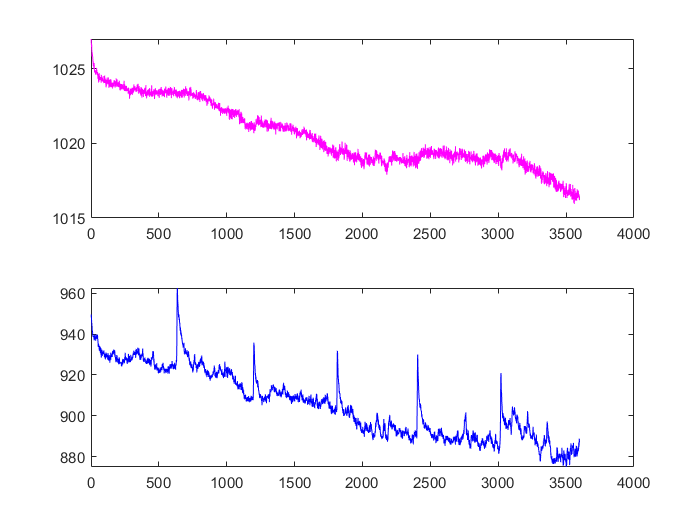

figure
subplot(2,1,1)
plot(raw_reference,'m')
subplot(2,1,2)
plot(raw_signal,'b')

# Use function get_zdFF.m to analyze data

zdFF = get_zdFF(raw_reference,raw_signal);

Plot z-score dF/F

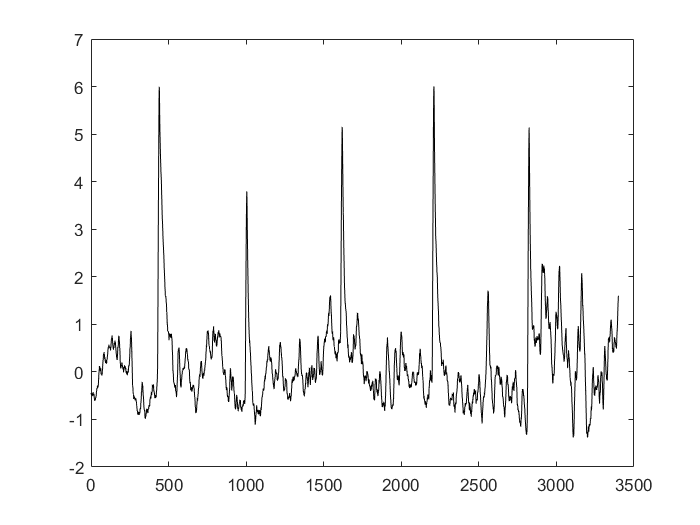

figure
plot(zdFF,'k')

# Analysis step by step

### Smooth data

smooth_win = 10;
smooth_reference = movmean(raw_reference,smooth_win);
smooth_signal = movmean(raw_signal,smooth_win);

Plot smoothed signals

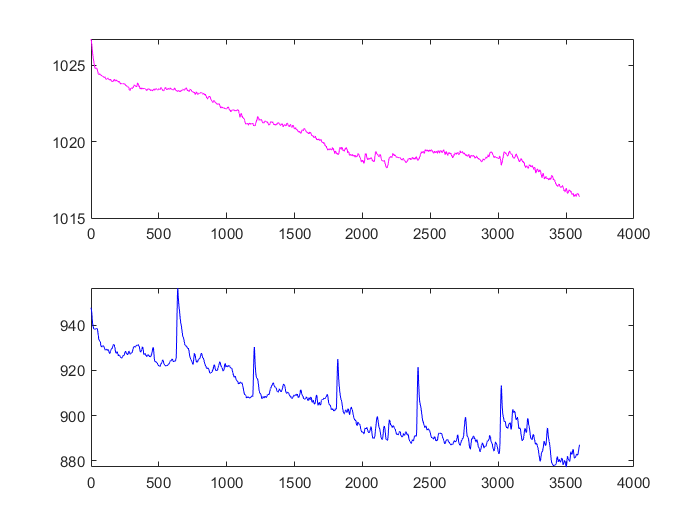

figure
subplot(2,1,1)
plot(smooth_reference,'m')
subplot(2,1,2)
plot(smooth_signal,'b')

### Remove slope using airPLS algorithm (airPLS.m)

lambda = 5e9;
order = 2;
wep = 0.1;
p = 0.5;
itermax = 50;

[reference,base_r]= airPLS(smooth_reference,lambda,order,wep,p,itermax);
[signal,base_s]= airPLS(smooth_signal,lambda,order,wep,p,itermax);

Plot slopes

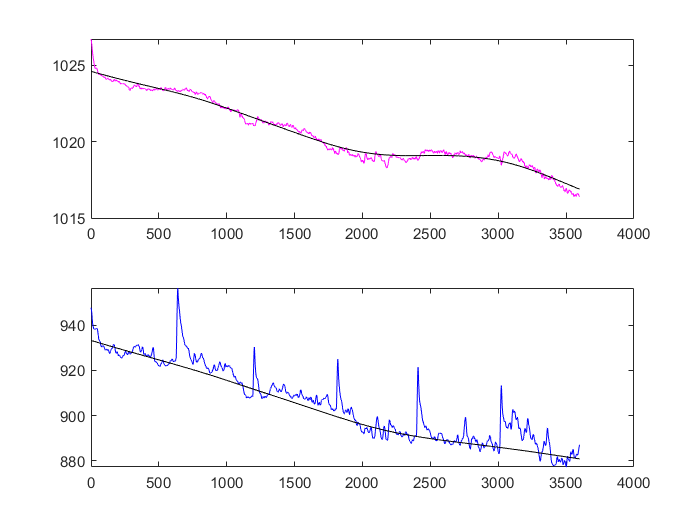

figure
subplot(2,1,1)
plot(smooth_reference,'m')
hold on
plot(base_r,'k')
hold off
subplot(2,1,2)
plot(smooth_signal,'b')
hold on
plot(base_s,'k')
hold off

### Remove the begining of recordings

remove = 200;
reference = reference(remove:end);
signal = signal(remove:end);

Plot signals

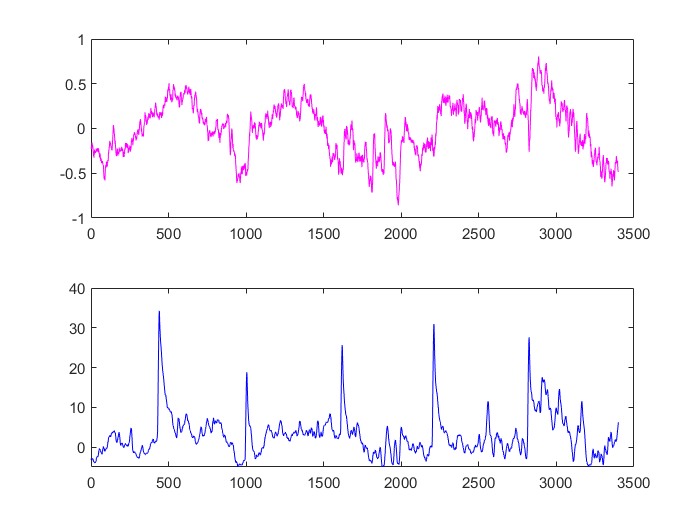

figure
subplot(2,1,1)
plot(reference,'m')
subplot(2,1,2)
plot(signal,'b')

### Standardize signals

z_reference = (reference - median(reference)) / std(reference);
z_signal = (signal - median(signal)) / std(signal);

Plot signals

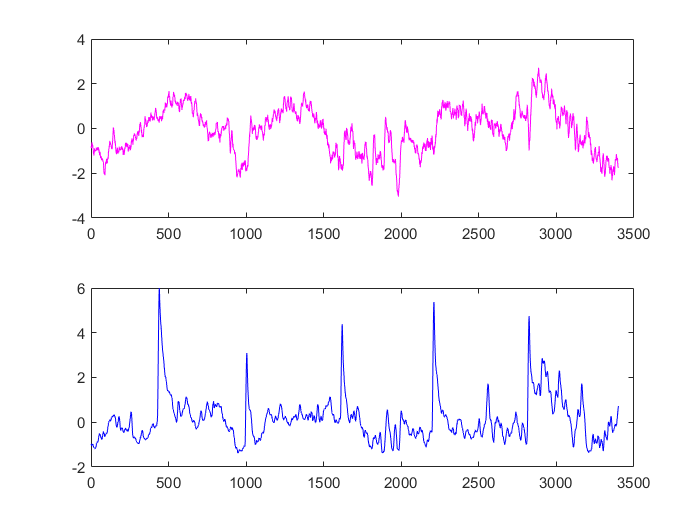

figure
subplot(2,1,1)
plot(z_reference,'m')
subplot(2,1,2)
plot(z_signal,'b')

### `Fit reference signal to calcium signal using non negative robust linear regression`

fitdata = fit(z_reference',z_signal',fittype('poly1'),'Robust','on');

Plot fit

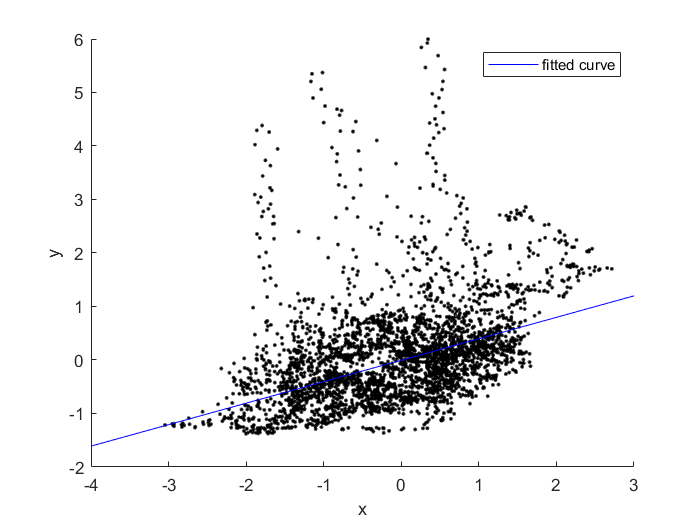

figure
hold on
plot(z_reference,z_signal,'k.')
plot(fitdata,'b')
hold off

### `Align reference to signal`

z_reference = fitdata(z_reference)';

Plot aligned signals

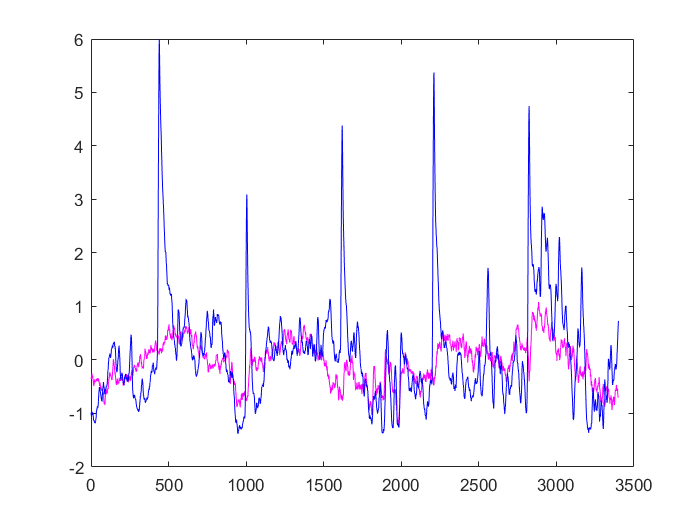

figure
plot(z_reference,'m')
hold on
plot(z_signal,'b')
hold off

### `Calculate z-score dF/F`

zdFF = z_signal - z_reference;

`Plot z-score dF/F`

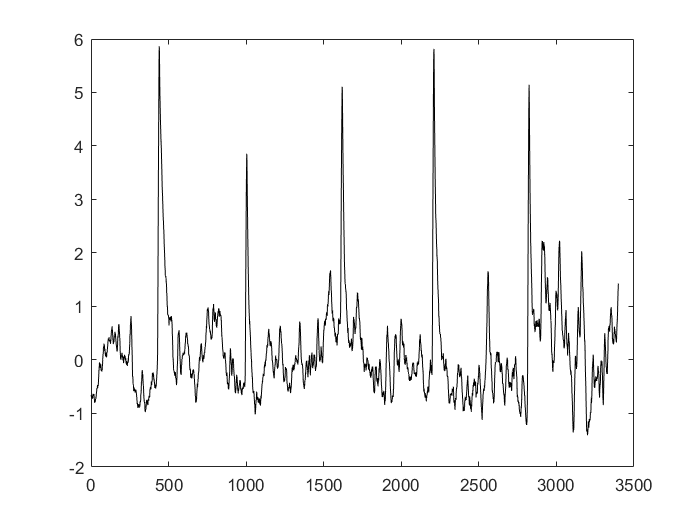

figure
plot(zdFF,'k')

# `Contact us`

If you have any questions please contact us: [ekaterina.martianova.1@ulaval.ca](mailto:ekaterina.martianova.1@ulaval.ca)